% This section does not work ! I am bad at functions and telling matlab
% where to go in the database :)
clear all
findEchoData('echogramsAntarctic.txt', '_Antarctica_BaslerMKB')

% ex: load in echogram data from first row in ech0Table.mat
load("echoTable.mat");
file = string(echoTable{1,1})
fileData = string(echoTable{1,2})
load(file);
load(fileData);

% generate echogram? ***FIX***
h_fig = figure;
h_axes = axes;
imagesc(lp(Data),'parent',h_axes);
colormap(h_axes,1-gray(256));
xlabel('Range line','parent',h_axes);
ylabel('Range bin','parent',h_axes);



Surface = interp1(Time,1:length(Time),layerData{1}.value{2}.data);
Bottom = interp1(Time,1:length(echo.Time),layerData{2}.value{2}.data);
Surface = interp1(GPS_time,Surface,GPS_time);
Bottom = interp1(GPS_time,Bottom,GPS_time);

hold(h_axes,'on');
plot(Surface,'m--','parent',h_axes);
plot(Bottom,'r--','parent',h_axes);
hold off

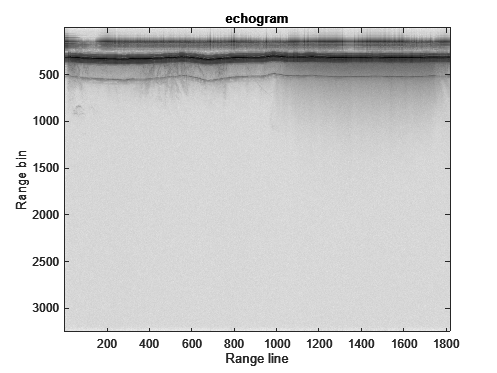

clear all
file = 'ALT_Data_20231209_01_001.mat';
imgFile = 'Data_img_01_20231209_01_001.mat';


addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layerData\20231209_01
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20231209_01

dispEcho(imgFile)